clc, clear
addpath('functions')
% net = googlenet;
load('net5.mat')
% temp_net = resnet50;

% imds_set 생성

[imds_set, label_set] = generate_image_set('..\images\train\');

% 각 클래스별 학습
featureLayer = 'loss3-classifier';
classifiers = train_concat_model(net,imds_set,featureLayer,false);

% 특징 추출
imds = imageDatastore('..\images\train\',"IncludeSubfolders",true,'LabelSource',"foldernames");
result = predict_concat_model(net, classifiers,imds,label_set,featureLayer,false);


X = table2array(result(:,1:end-1));
y = table2array(result(:,end));


class_list = unique(y);

for i=1:length(class_list)
    class_name = class_list(i);
    feature_data = X(:,i);
    scaled_data = (feature_data - min(feature_data))/(max(feature_data)-min(feature_data));
    
    subplot(2,5,i)
    boxplot(scaled_data,y)
    title(class_list(i))
    xtickangle(90)
end


% test 정확도
imds_te = imageDatastore('..\images\validation\',"IncludeSubfolders",true,'LabelSource',"foldernames");


result_test = predict_concat_model(net, classifiers,imds_te,label_set,featureLayer,false);
X_test = table2array(result_test(:,1:end-1));
y_test = table2array(result_test(:,end));

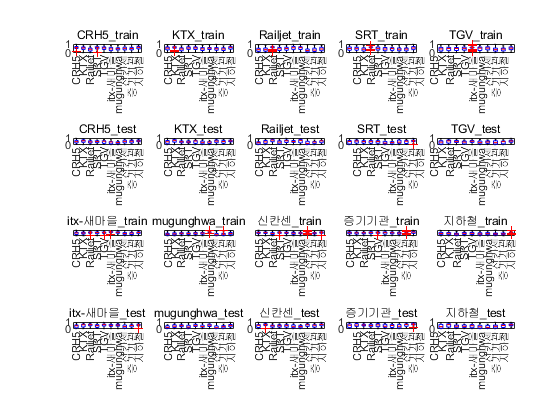

figure
class_list = unique(y);


for i=1:length(class_list)
    if i<=5
        j=i;
    else
        j=i+5;
    end
    class_name = class_list(i);
    feature_data = X(:,i);
    feature_data_test = X_test(:,i);
    scaled_data = (feature_data - min(feature_data))/(max(feature_data)-min(feature_data));
    scaled_data_test = (feature_data_test - min(feature_data_test))/(max(feature_data_test)-min(feature_data_test));
    subplot(4,5,j)
    boxplot(scaled_data,y)

    title(strcat(string(class_list(i)),'\_train'))
    xtickangle(90)

    subplot(4,5,j+5)
    boxplot(scaled_data_test,y_test)

    title(strcat(string(class_list(i)),'\_test'))
    xtickangle(90)
    
end


% for i=1:length(class_list)
%     feature_data = X_test(:,i);
%     scaled_data = (feature_data - min(feature_data))/(max(feature_data)-min(feature_data));
%     
%     subplot(2,5,i)
%     boxplot(scaled_data,y_test)
%     title(class_list(i))
%     xtickangle(90)
% end


bc = 1;
temp1 = templateSVM('KernelFunction','linear', 'PolynomialOrder', [], 'KernelScale', 'auto', 'BoxConstraint', bc, 'Standardize', true);
temp2 = templateSVM('KernelFunction','polynomial', 'PolynomialOrder', 2, 'KernelScale', 'auto', 'BoxConstraint', bc, 'Standardize', true);
temp3 = templateSVM('KernelFunction','polynomial', 'PolynomialOrder', 3, 'KernelScale', 'auto', 'BoxConstraint', bc, 'Standardize', true);
temp4 = templateSVM('KernelFunction','gaussian', 'PolynomialOrder', [], 'KernelScale', 0.43, 'BoxConstraint', bc, 'Standardize', true);
temp5 = templateSVM('KernelFunction','gaussian', 'PolynomialOrder', [], 'KernelScale', 1.7, 'BoxConstraint', bc, 'Standardize', true);
temp6 = templateSVM('KernelFunction','gaussian', 'PolynomialOrder', [], 'KernelScale', 6.9, 'BoxConstraint', bc, 'Standardize', true);

temps = {temp1,temp2,temp3,temp4,temp5,temp6};
svms = {};

for i=1:6
    svm = fitcecoc(X,y,'Learners',temps{i},'Coding','onevsone');
    svms{i} = svm;
end

preds = {};
accuracies_te = {};
for i=1:6
    pred = predict(svms{i},X_test);
    preds{i} = pred;
    acc_te = sum(pred==y_test)/length(y_test);
    accuracies_te{i} = acc_te;
end


% train 정확도
preds = {};
accuracies_tr = {};
for i=1:6
    pred = predict(svms{i},X);
    preds{i} = pred;
    acc_tr = sum(pred==y)/length(y);
    accuracies_tr{i} = acc_tr;
end



cell2mat(accuracies_tr)
cell2mat(accuracies_te)